### 4.1. Funções básicas de controle

Controle proporcional puro: $u = k_p \, e(t)$         $C(s) = k_p$

P = tf(1,[1 1])^3

P =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties


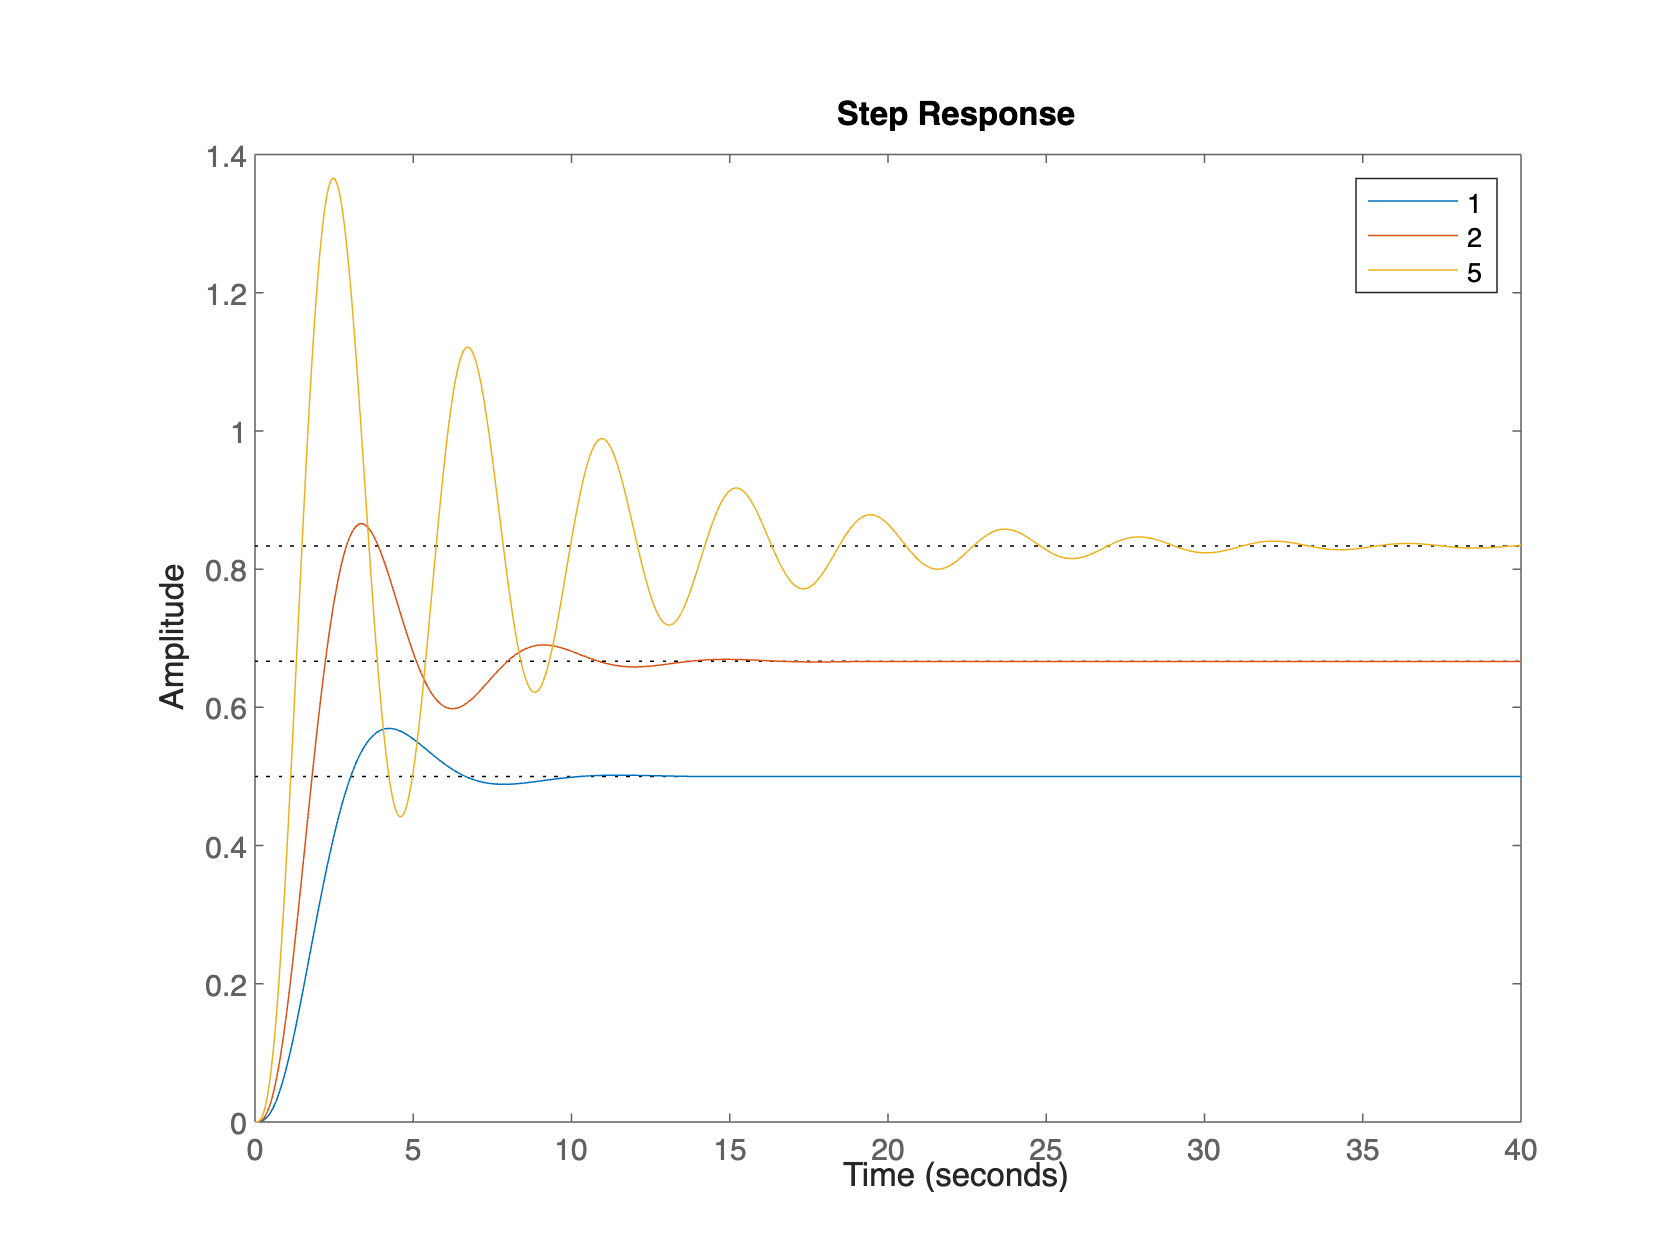

kp_vec = [1 2 5];
figure;
for kp = kp_vec
    C = kp;
    G = P*C/(1+P*C);
    step(G); hold all;
end
legend(num2str(kp_vec'))

Existe um erro de regime permanente, que pode ser calculado através do teorema do valor final:


$$y(\infty)= \lim_{s->0}sY(s)$$


Para uma entrada degrau: $Y = G_{yu} \, U = G_{yu} \frac{1}{s}$

Logo: $y(\infty)= G_{yu}(0)$

O erro de rastreio é $e(\infty) =1-y(\infty)$


$$e(\infty) = 1 - \frac{PC(0)}{1+PC(0)} = \frac{1}{1+PC(0)}
$$


Para o controlador com ganho proporcional puro:


$$e(\infty) =  \frac{1}{1+k_p \,P(0)}
$$


Uma maneira de resolver o problema do erro de regime permanente é introduzir um termo "feedforward":


$$u = k_p \, e(t) + u_{ff}$$


onde $u_{ff} = \frac{r}{P(0)}$

O problema: requer conhecimento exato da dinâmica da planta $P(s)$, ou é ajustado manualmente.

Outra alternativa para remover o erro de regime permanente é introduzir o termo integral:

Controle proporcional integral:    $u = k_p \, e(t) + k_i \int_0^t e(\tau)d\tau$       $C(s) = k_p + \frac{k_i}{s}$

P = tf(1,[1 1])^3

P =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties


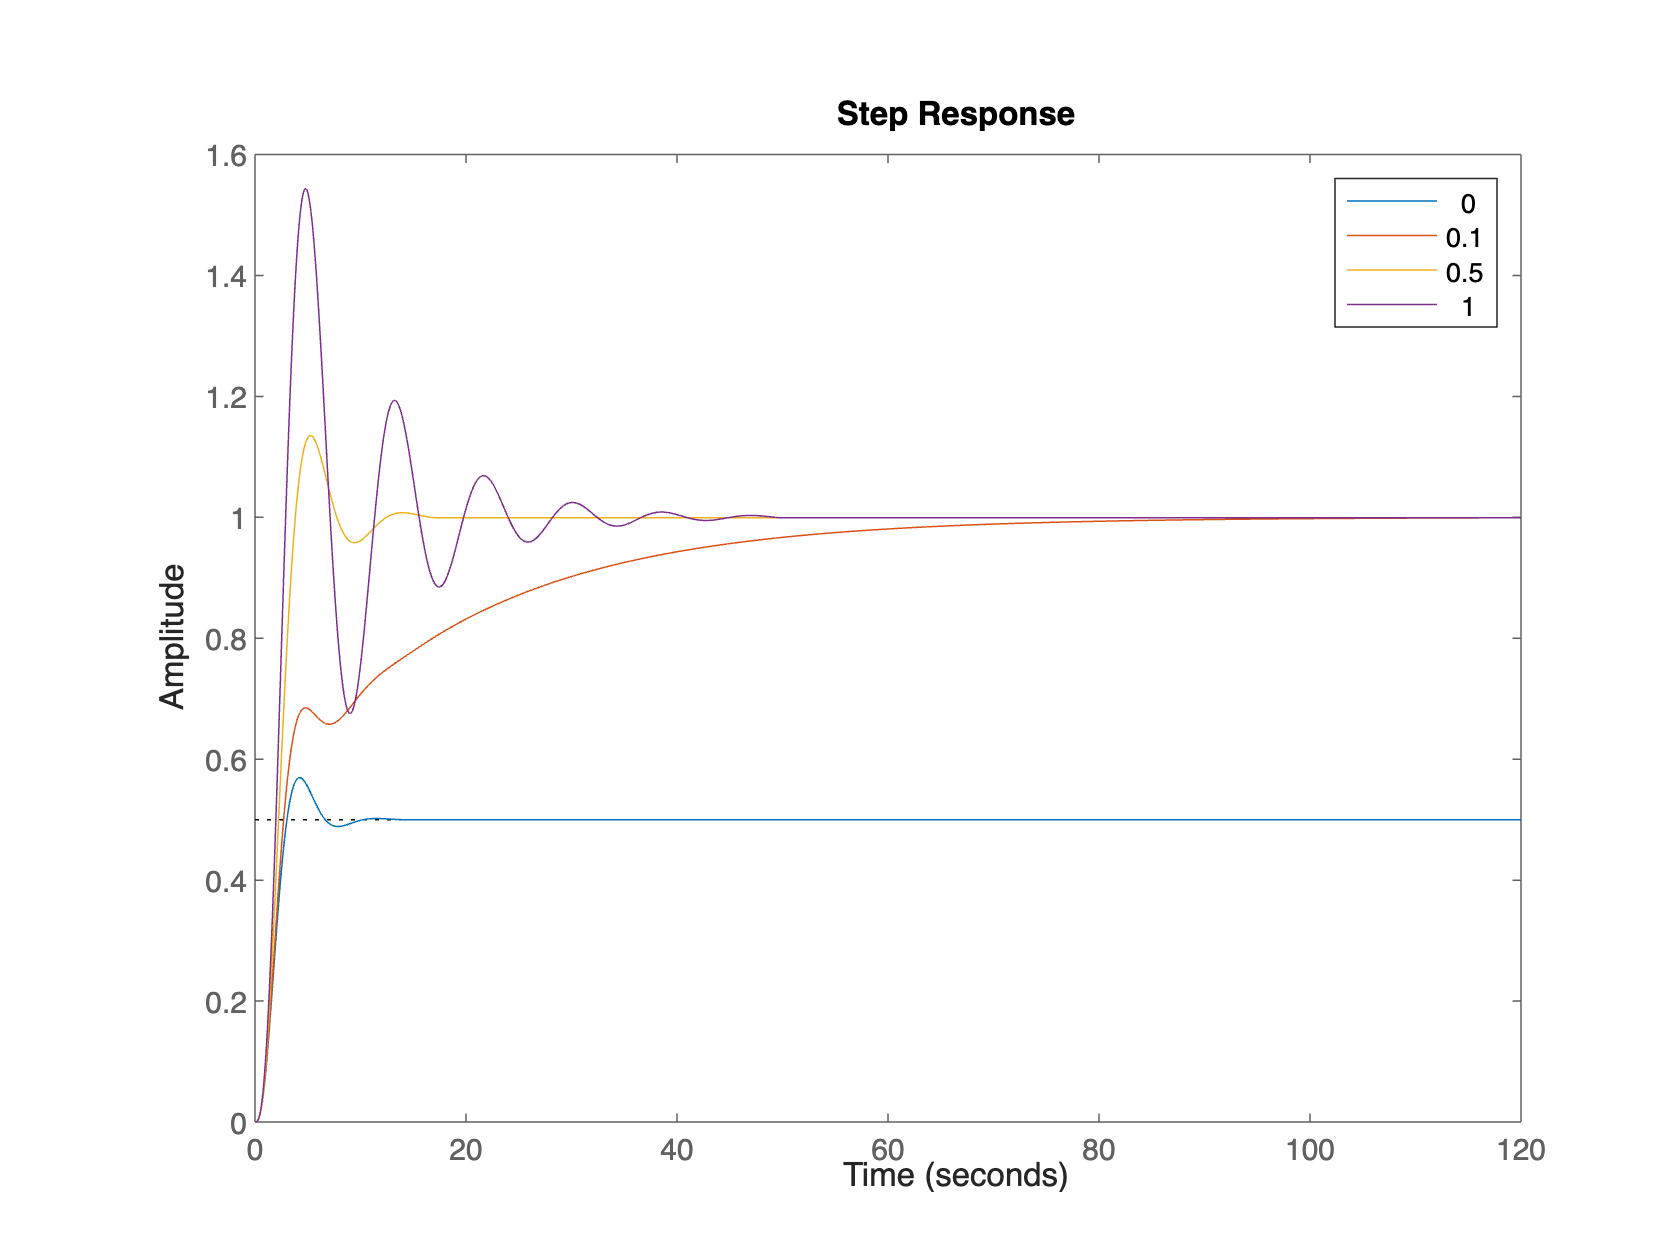

ki_vec = [0 0.1 0.5 1];
figure;
kp = 1;
for ki = ki_vec
    C = kp + ki*tf(1,[1 0]);
    G = P*C/(1+P*C);
    step(G); hold all;
end
legend(num2str(ki_vec'))

Controle proporcional integral derivativo: 

 $u = k_p \, e(t) + k_i \int_0^t e(\tau)d\tau + k_d \frac{d e}{dt}$  ,       $C(s) = k_p + \frac{k_i}{s} +k_d \,s$

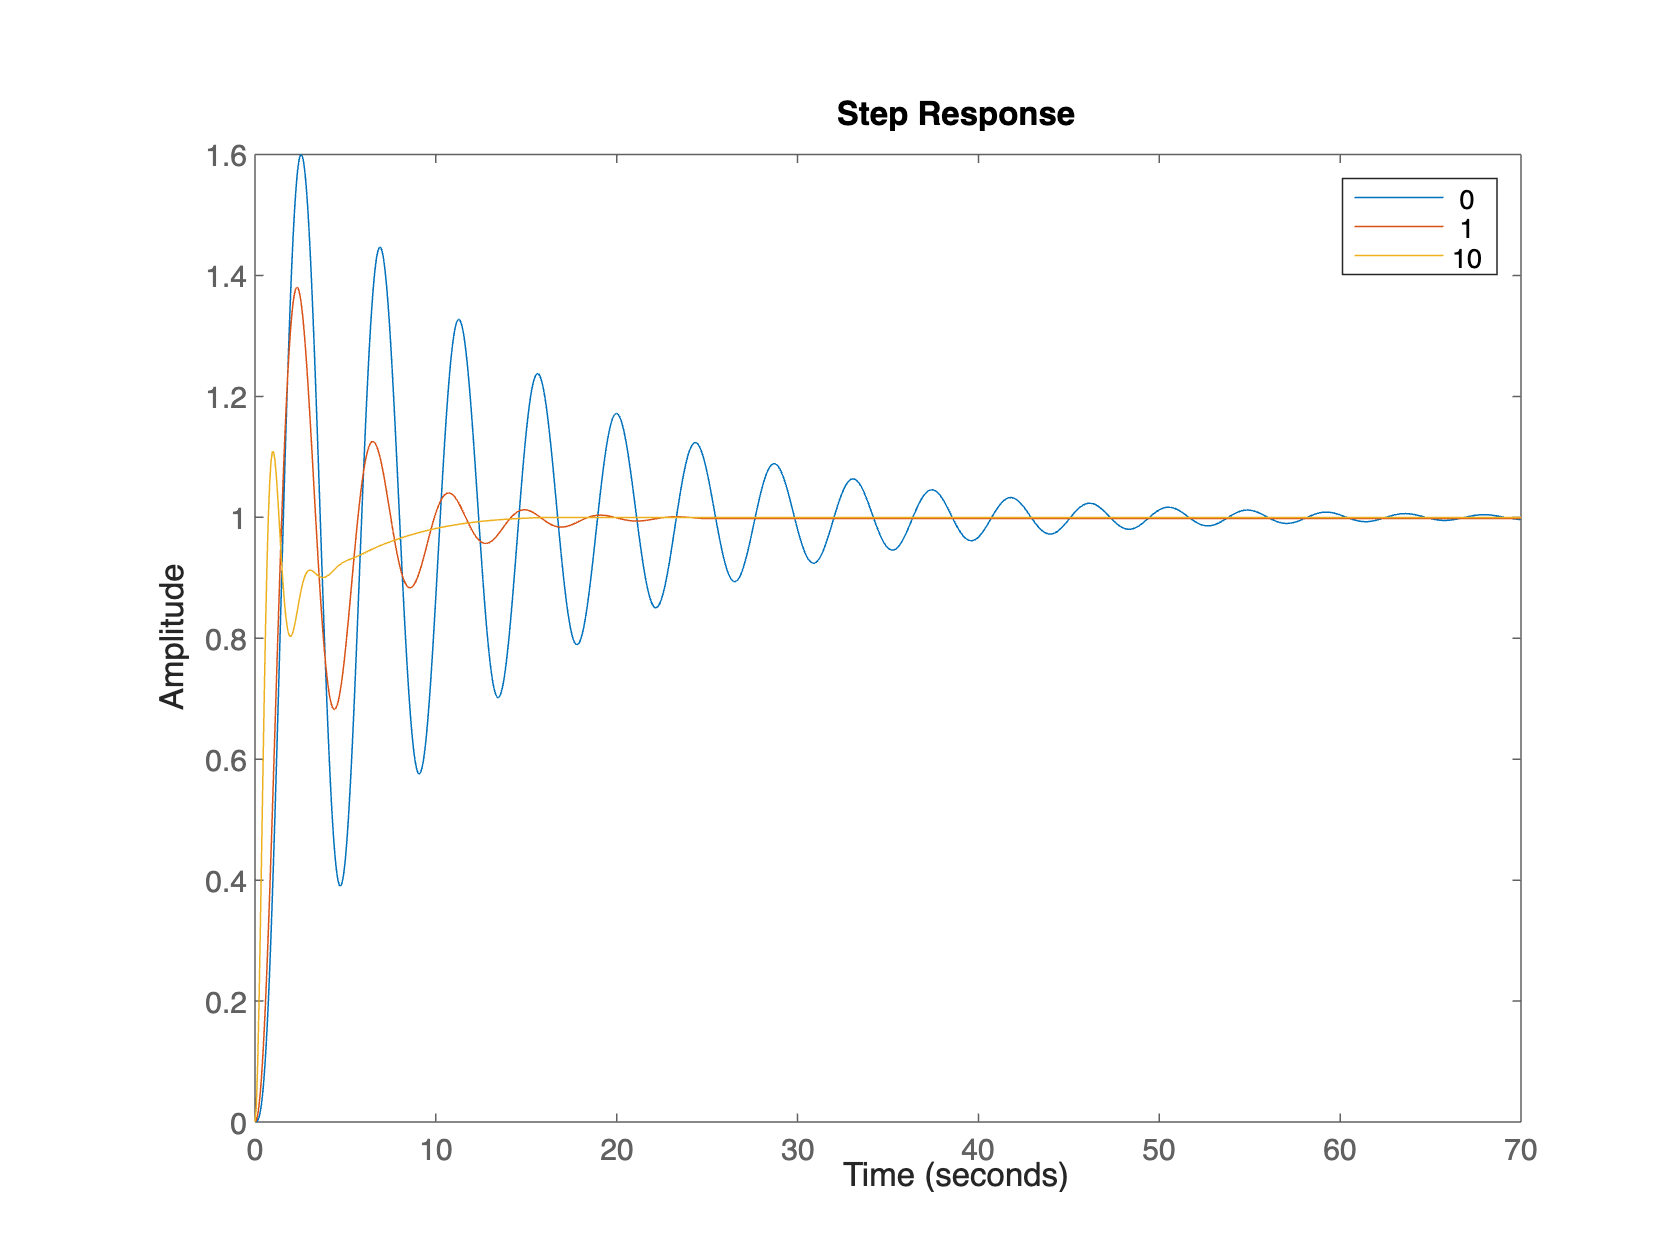

P = tf(1,[1 1])^3;
ki = 1;
kd_vec = [0 1 10];
figure;
kp = 5;
for kd = kd_vec
    C = kp + ki*tf(1,[1 0]) + kd*tf([1 0],1);
    G = P*C/(1+P*C);
    step(G); hold all;
end
legend(num2str(kd_vec'))